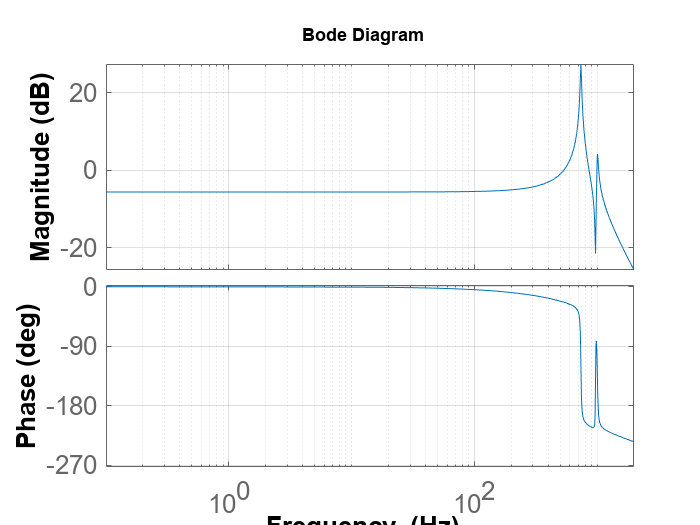

load MSD2024_P2_Plant.mat  % Load plant transfer function

s = tf('s');

P = G;

% Define bode options
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
opts.XLim= [0.1 2000];
opts.PhaseVisible = 'on';
opts.PhaseWrapping = 'off';
opts.Grid = 'on';
opts.XLabel.String = 'Frequency';
opts.XLabel.FontSize = 16;
opts.XLabel.FontWeight = 'bold';
opts.YLabel.String = {'Magnitude','Phase'};
opts.YLabel.FontSize = 16;
opts.YLabel.FontWeight = 'bold';
opts.TickLabel.FontSize = 16;

figure(1);clf(1);
bode(P,opts)

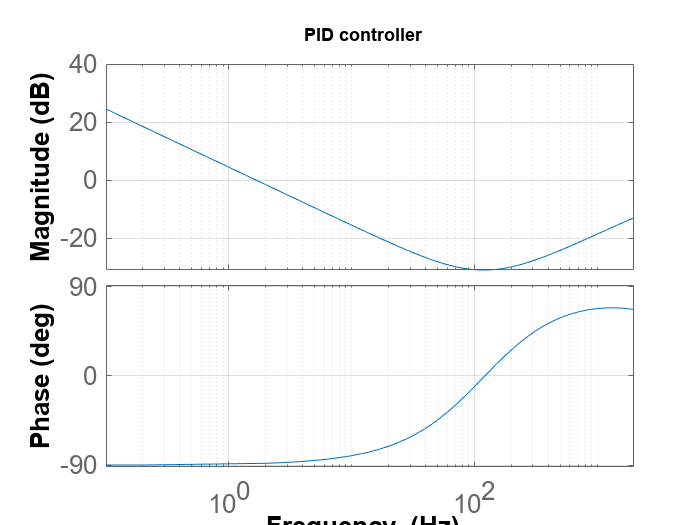


%(A.1)Design a feedback controller C(s) with PM >= 60 deg; Gm >= 6 dB;
%MM <= 6 dB

wc = 1000*2*pi; % Choose appropriate wc
a = 7; % Differentiator band
kp = (1/a)*(1/abs(freqresp(P,wc)));
wi = wc/10; 
wd = wc/a; 
wt = wc*a; 

C_pi = (kp/a)*(1 + (wi/s));

%Best solution PID controller
C_pdi = (kp/a)*(1 + wi/s)*(s/wd + 1)/(s/wt + 1);

C_pd = (kp/a)*(s/wd + 1)/(s/wt + 1); 

figure(1);clf(1);
bode(C_pdi,opts);
title('PID controller')
grid on; grid minor;

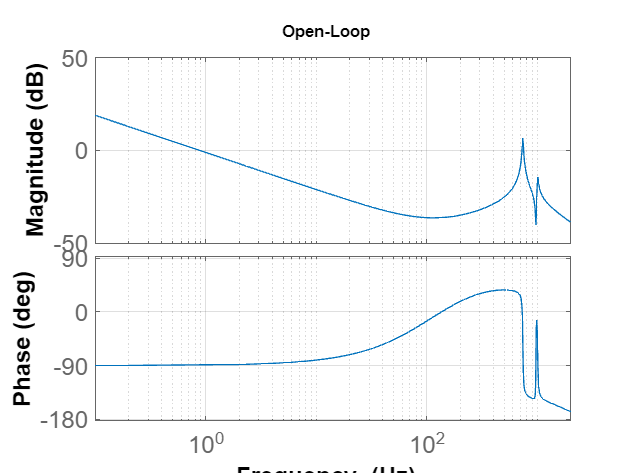


% Open-Loop
L = P*C_pdi; 
figure(2);clf(2);
bode(L,opts);
title('Open-Loop')
grid on; grid minor;

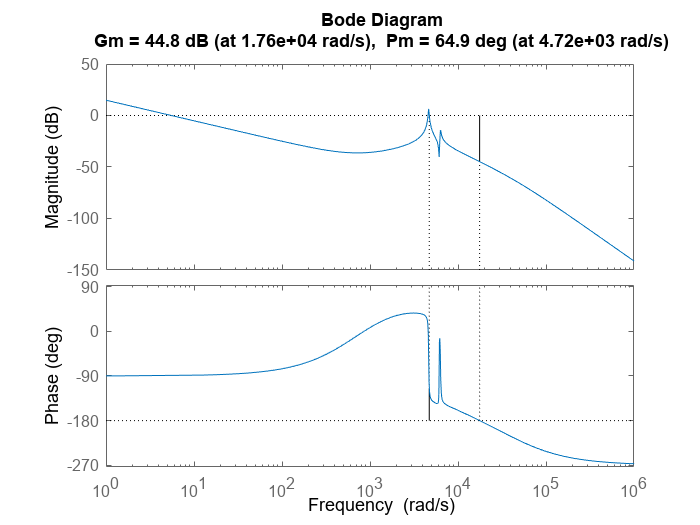


figure(3); margin(L); % Evaluate Gain and Phase Margins

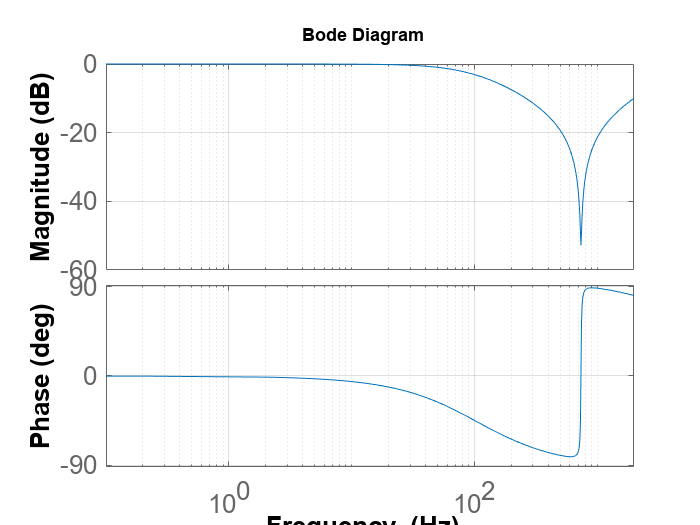


% Design a Skewed Notch Filter ( best solution ) to maximize fc
%Q = 1/10; % Notch at second resonance
%wnf = 739.809*2*pi;

%LP = 1/((s/(wc)) + 1);
%LP = 1/((s/wc)^2 + (s/(Q*wc)) + 1);
w1 = 739.809*2*pi; w2 = 1015.924*2*pi; w3 = 10*2*pi;
Q1 = 60; Q2 = 1/10;
Q3 = 60; Q4 = 1/10; % Change both ratio (Q1/Q2) and absolute value (|Q1|,|Q2|)
N = ((s/w1)^2 + (s/(Q1*w1)) + 1)/((s/w2)^2 + (s/(Q2*w2)) + 1);
N2 = ((s/w3)^2 + (s/(Q4*w3)) + 1)/((s/w3)^2 + (s/(Q3*w3)) + 1);
figure(1);clf(1);
bode(N,opts) % Observe notch depth and width

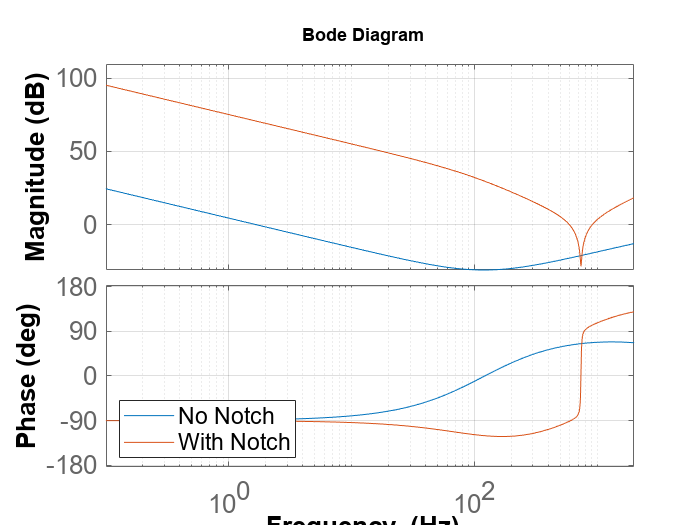


%Increase of the Bandwidth from 1 to 6 kHz
wc = 5850*2*pi; 
a = 7; % Differentiator band
kp = (1/a)*(1/abs(freqresp(P,wc)));
wi = wc/10; 
wd = wc/a; 
wt = wc*a; 

%C2_pi = kp*(1 + (wi/s))*LP;

%Designed controller with Notch filter
C2_pdi = (kp/a)*(1 + wi/s)*(s/wd + 1)/(s/wt + 1)*N;
C2_pdi2 = (kp/a)*(1 + wi/s)*(s/wd + 1)/(s/wt + 1)*N*N2;
C2_pd = (kp/a)*(s/wd + 1)/(s/wt + 1);

%(A.2) Plot the frequency response of the designed controller,
%complementary sensitivity and sensitivity of the designed system

figure(2);clf(2);
bode(C_pdi,C2_pdi,opts)
legend('No Notch','With Notch',Location='southwest')
grid on; grid minor;

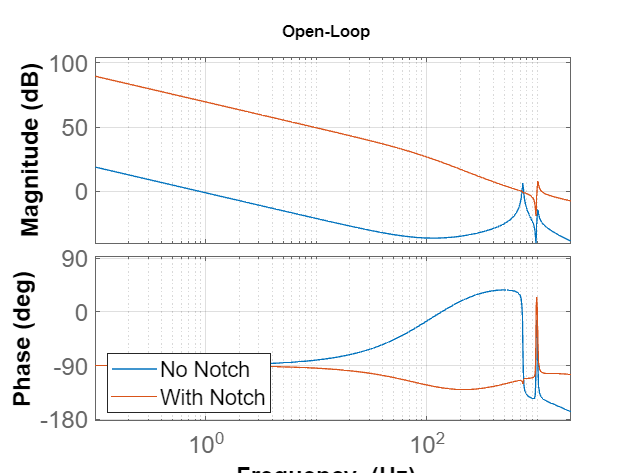


% Open-Loop
L2 = P*C2_pdi;
L22 = P*C2_pdi2;
figure(2);clf(2);
bode(L,L2,opts);
title('Open-Loop')
legend('No Notch','With Notch',Location='southwest')
grid on; grid minor;

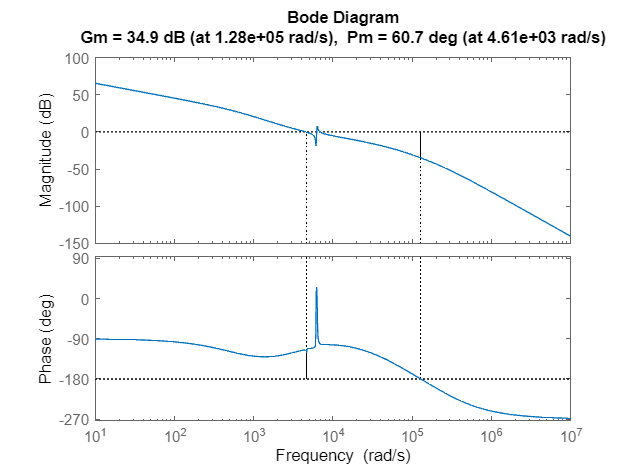


figure (3); margin(L2)

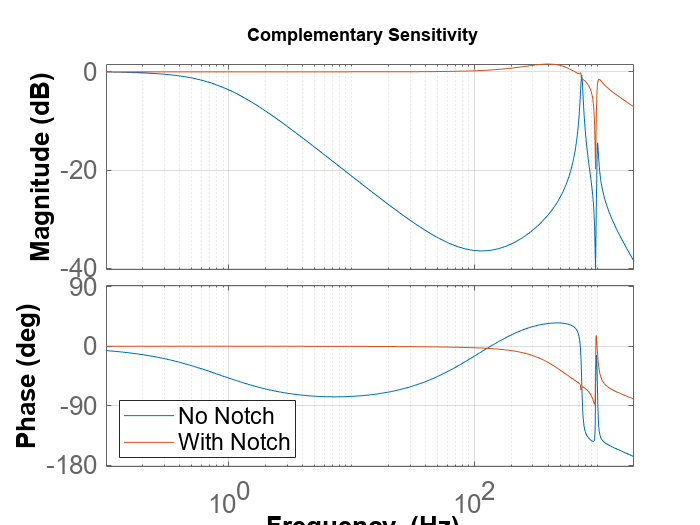


T = L/(1+L); % Complementary Sensitivity
T2 = L2/(1+L2);
S = 1/(1+L); % Sensitivity
S2 = 1/(1+L2);
T22 = L22/(1+L22);
S22 = 1/(1+L22);

figure(3);clf(3);
bode(T,T2,opts); title('Complementary Sensitivity')
legend('No Notch','With Notch',Location='southwest')
grid on; grid minor;

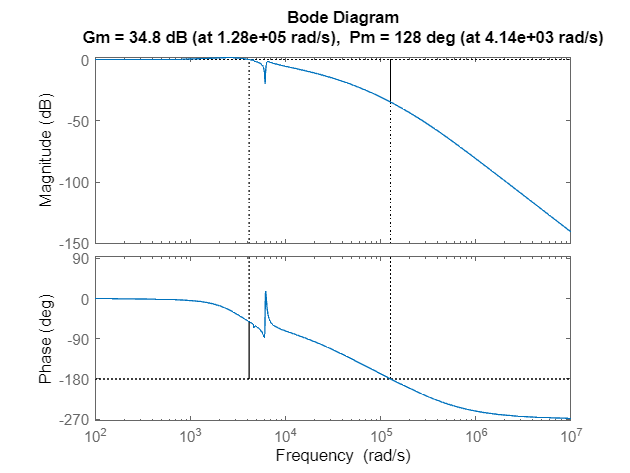

margin(T2)

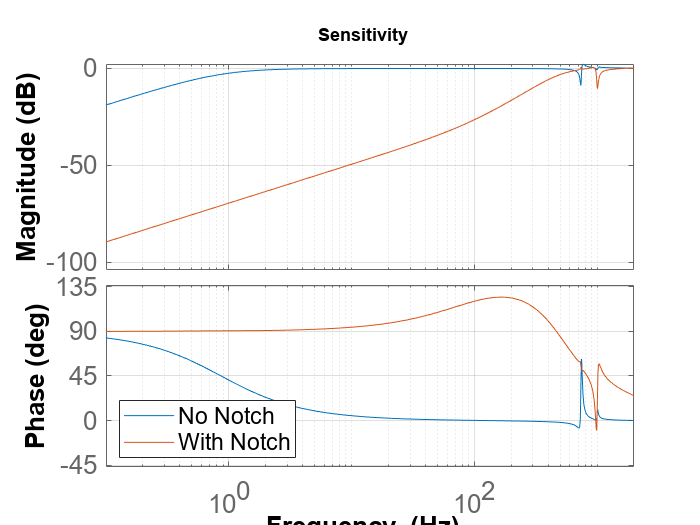


figure(4);clf(4);
bode(S,S2,opts); title('Sensitivity')
legend('No Notch','With Notch',Location='southwest')
grid on; grid minor;

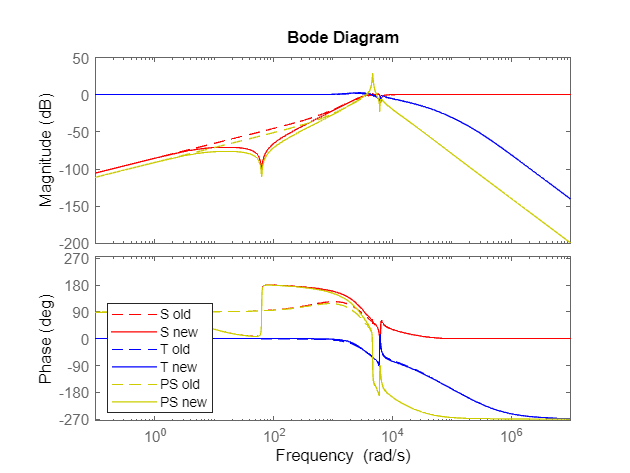


%(A3.1) Computation of real error for the feedback controller

%Definition of sinusoidal signals r, d and n at 10 Hz

f = 10; %Hz

Period = 1 / f; %s

t = 0:Period:1; %Time vector

%Definition of amplitudes of signals

R = 10e-5; %10 um

D = 20; %20V

N_disturbance = 10e-8; %10 nm

r = R * sin(2 * pi * f * t); %Reference sinusoidal signal

d = D * sin(2 * pi * f * t); %Process disturbance sinusoidal signal

n = N_disturbance * sin(2 * pi * f * t); %Output disturbance sinusoidal signal

%Definition of frequencies responses of sensitivity and complementary
%sensitivity at 10 Hz

omega = 2 * pi * f;

S2_10Hz = abs(freqresp(S22, omega)); %Sensitivity at 10 Hz

T2_10Hz = abs(freqresp(T22, omega)); %Complementary sensitivity at 10 Hz

P_10Hz = abs(freqresp(P, omega)); %Plant at 10 Hz

%Computation of real error

e_real = sqrt((S2_10Hz * R)^2 + (P_10Hz * S2_10Hz * D)^2 + (T2_10Hz * N_disturbance)^2);

PS2 = G/(1+L2);
PS22 = G/(1+L22);

bode(S2,"r--",S22,"r",T2,"b--",T22,"b",PS2,"y--",PS22,"y")
legend("S old","S new","T old","T new","PS old","PS new", location = "southwest")


%(A3.2) How can we reduce real error?
%---> Real error depends on sensitivity, complementary sensitivity and
%disturbance and reference signals. Sensitivity and Complementary
%sensitivity depends on the open-loop gain L2 ( T2 = L2 / ( 1 + L2 ),
%S2 = 1 / (1 + L2) ):

%1.) Act on sensitivity and complementary sensitivity frequency responses
%at 10 Hz - This involves the increase in open-loop gain L2 at 10 Hz.
%However, compromises have to be taken since a too high open-loop gain can
%definitely reduce the sensitivity ( which appears twice in the real error
%) BUT MAY INCREASE COMPLEMENTARY SENSITIVITY

%2.) Design a pre-filter to decrease the amplitude of the reference signal
%r

%% Stability Check
% pole(), step(), impulse(), 
% isstable() - doesn't consider s=0 stable!

%(A3.3) Design a pre-filter to reduce the amplitude of the reference signal

%Try-out with low pass filter

Q = 1/10000;

Pre_filter = 1 / ((s/wc)^2 + (s/(Q*wc) + 1));

Pre_filter_10Hz = abs(freqresp(Pre_filter, omega));

%New Reference r

rf = Pre_filter * r;

R_new = Pre_filter_10Hz * R;

stable_open = isstable(L2);
stable_close = isstable(T2);

% Define input-output variables - Connect pre-filter to reduce r
P.u='u'; P.y='x';
C2_pdi.u='e'; C2_pdi.y='v';
Pre_filter.u = 'r'; Pre_filter.y = 'rf';

%CASE 1: P-Gain controller with Notch filter

S1 = sumblk("e = rf - y");
S2 = sumblk("u = d + v");
S3 = sumblk("y = x + n");

P.u='u'; P.y='x';
C2_pdi.u='e'; C2_pdi.y='v';
Pre_filter.u = 'r'; Pre_filter.y = 'rf';


Tconnect = connect(P,C2_pdi,Pre_filter,S1,S2,S3,"r","y");

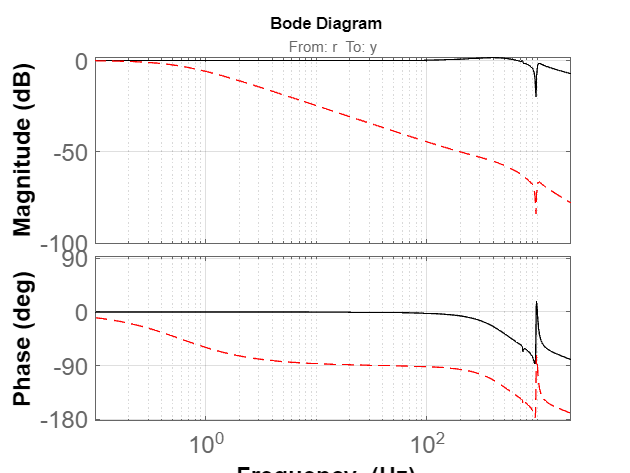


L_new = 1 / (1/Tconnect - 1);

Tconnect_10Hz = abs(freqresp(Tconnect, omega));

e_real_new = sqrt((S2_10Hz * R_new)^2 + (P_10Hz * S2_10Hz * D)^2 + (Tconnect_10Hz * N_disturbance)^2);

figure(1);clf(1);
bode(T2,'k',Tconnect,'r--',opts) % Compare

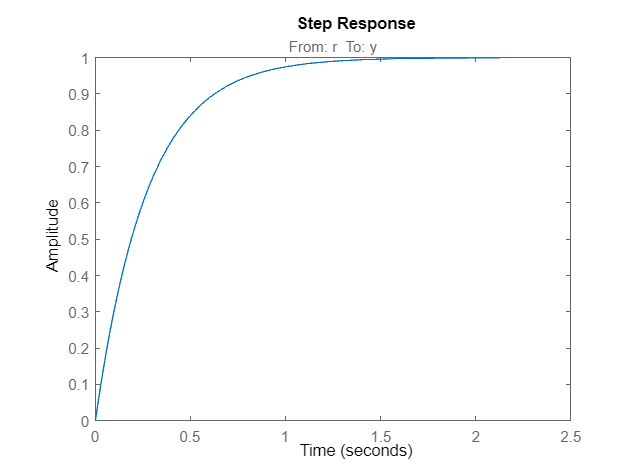


%(A.3) Plot the step response of the system

step(Tconnect)


%(A.4 - A.5) Design a feedforward and plot the updated system response 

b = 7/10

b = 0.7000

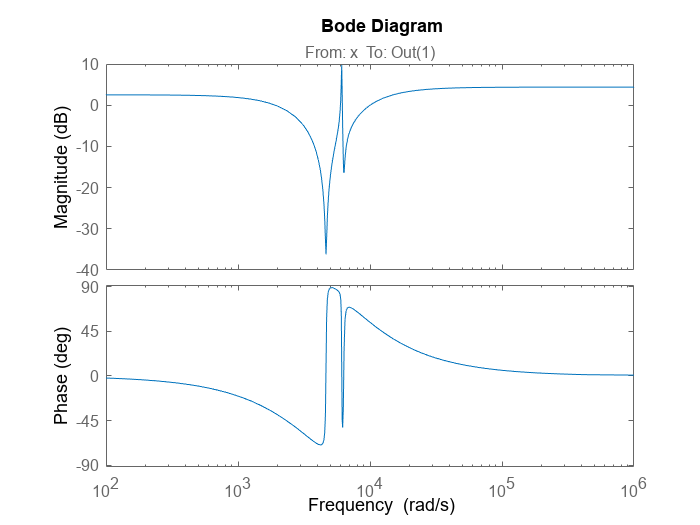


Q = 1/2;
Q2 = 1/1000;
wc2 = 1000*2*pi;
%F = 1/((s/(wc2)) + 1)/P;
F = b*(1/((s/(wc2)) + 1))*(1 / ((s/wc2)^2 + (s/(Q*wc2)) + 1))/P ; % Tryout for A.8

YtoN = 1/(1+L2);

bode(F)


% Is it proper (/strictly) proper? Tame it to make it proper!
isproper(F)

ans = logical
   1



isstable(F)

ans = logical
   1



S1 = sumblk("e = r - y");
S2 = sumblk("z = v + f");
S3 = sumblk("u = d + z");
S4 = sumblk("y = x + n");

P.u='u'; P.y='x';
C2_pdi.u = 'e'; C2_pdi.y = 'v';
F.u = 'r'; F.y = 'f'

F =
 
  From input "r" to output "f":
  4.123e29 s^5 + 3.662e33 s^4 + 2.616e37 s^3 + 2.223e41 s^2 + 3.778e44 s + 3.075e48
  ---------------------------------------------------------------------------------
   2.486e29 s^5 + 4.702e33 s^4 + 3.901e37 s^3 + 2.383e41 s^2 + 1.102e45 s + 2.3e48
 
Continuous-time transfer function.




Tconnect2 = connect(P,C2_pdi,F,S1,S2,S3,S4,"r","y");

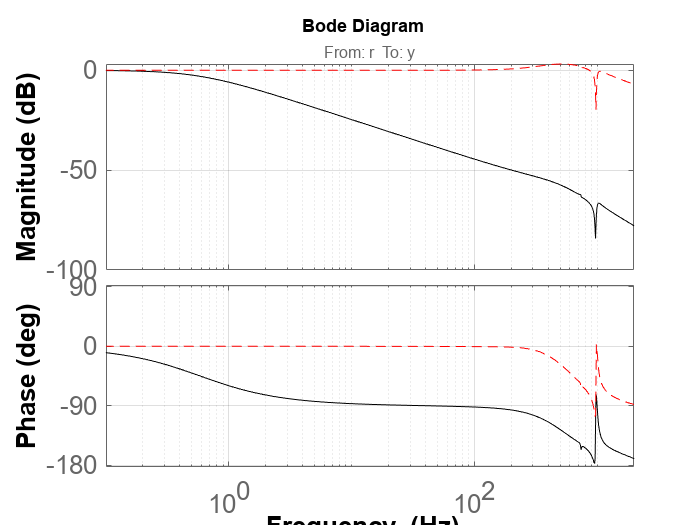


bode(Tconnect,'k',Tconnect2,'r--',opts) % Compare

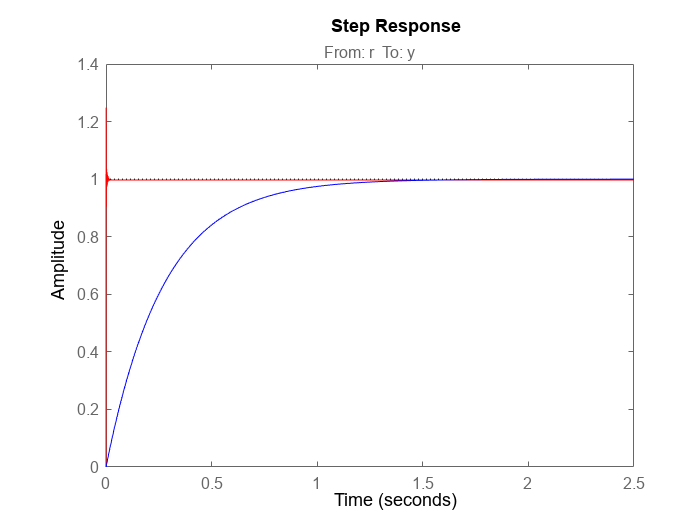


step(Tconnect2, 'r', Tconnect, 'b')

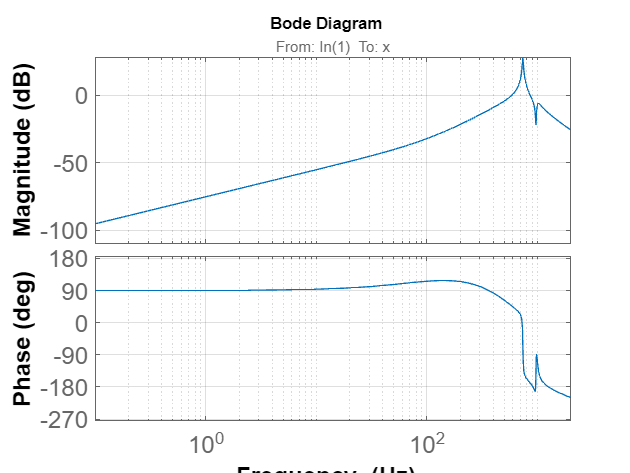


%%Transfer functions from r to y, d to y and n to y ( A.6 )

%Complementary sensitivity from r to y

GS2 = P / (1 + L2); %Process sensitivity function from d to y

%Sensitivity function from n to y

bode(GS2, opts)

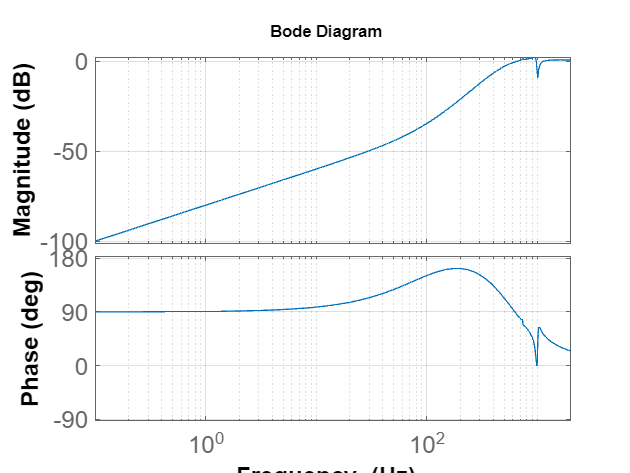


%Check if the noise transfer function is coherent with the requirements of
%the assignment

%Derivation of the open loop with feedforward - Tconnect2 is the
%complementary sensitivity of system with feedforward

L2ff = 1/(1/Tconnect2 - 1);

%Noise transfer function

TN = 1 / (1 + L2ff);

%Stability check

stable_open2 = isstable(L2ff);

stable_close2 = isstable(Tconnect2);

bode(TN,opts)


S2ff = 1/(1+L2ff);
T2ff = L2ff/(1+L2ff);

S2_10Hzff = abs(freqresp(S2ff, omega)); %Sensitivity at 10 Hz

T2_10Hzff = abs(freqresp(T2ff, omega)); %Complementary sensitivity at 10 Hz

P_10Hzff = abs(freqresp(P, omega)); %Plant at 10 Hz

%Computation of real error

e_realff = sqrt((S2_10Hzff * R)^2 + (P_10Hzff * S2_10Hzff * D)^2 + (T2_10Hzff * N_disturbance)^2);

%%CASE 1: P-gain controller with Notch filter
%----> Varying the Q1 and Q2 to respectively 20 and 10, the bandwidth
%will start from 0 and go up to about 200, then phase gets greater than
%-180 deg and then again will go below - DISCONTINUITY IN BANDWIDTH
%----> With Q1 = 20 and Q2 = 10 instead, the closed loop will be shifted
%towards less frequencies
%(GM = -6.78 dB; PM = -0.583 deg for Q1 = 20; Q2 = 15; wnf = 100*2*pi; wc = 100*2*pi)
%-----> Not the best solution because phase margin remains little even for
%high crossover frenquencies
%It needs a differentiator

%%With PI controller:

%Started with 1070 Hz to obtain Gm = 6.31 dB and Pm = 90.9 deg.
%BEST POSSIBLE NOTCH ( Q1 = 60 ; Q2 = 1/10 ; wnf = 739.809 ) ------>
%Increased Bandwidth from 1070 Hz to 1700 Hz.
%BEST POSSIBLE SKEWED NOTCH ( Q1 = 60 ; Q2 = 1/10 ; W1 = 739.809*2*PI ;
%W2 = 1006.341*2*PI ) ----> Increased the bandwidth from 1070 Hz to 2100 Hz
%BEST POSSIBLE LOW PASS FILTER 2nd ORDER ( Q = 1/10 ) ---> Increased
%Bandwidth from 1070 Hz to 2000 Hz

%%With PID controller - fc = 1000 Hz; a = 7 ----> Meet all the requirements
%%( Gm = 44.8 dm; Pm = 64.9 deg ). Applying a Notch filter at the first
%%resonance ( Q1 = 90 and Q2 = 10 ) can maximize the bandwidth to fc = 1450
%%Hz while meeting all the requirements. System is not stable.
%Applying a skewed notch filter ( Q1 = 60 & Q2 = 1/10; w1 = 739.809*2*pi; w2 = 1015.924*2*pi; ) instead can maximize the crossover
%frequency to 5850 Hz. Low Pass filters do not add important features to
%the Bode plot

signals = load("MSD2024_P2_Signals.mat")

signals = struct with fields:
    e: [507229×1 double]
    r: [507229×1 double]
    u: [507229×1 double]
    y: [507229×1 double]


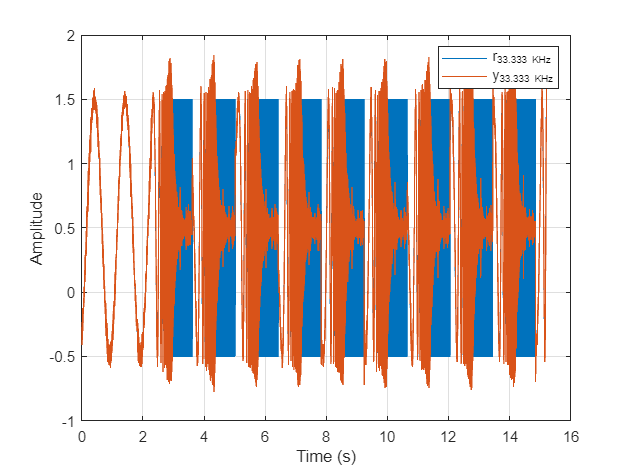


Ts          = 30e-6; % [s] sample time
Fs          = 1/Ts; % [Hz] Sample Frequency

r = signals.r;    % Input signal
u = signals.u;    % Control signal
y = signals.y;    % Measured output
e = signals.e;    % Error signal

N = length(r);    % Number of samples
t = (0:N-1) * Ts; % Time vector [s] % [s] time vector

% Plot Signals
figure(1); clf(1);
plot(t, r, 'DisplayName', 'r_{33.333 KHz}'); % Input signal
hold on;
%plot(t, u, 'DisplayName', 'u_{33.333 KHz}'); % Control signal
plot(t, y, 'DisplayName', 'y_{33.333 KHz}'); % Measured output
%plot(t, e, 'DisplayName', 'e_{33.333 KHz}'); % Error signal
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('show');

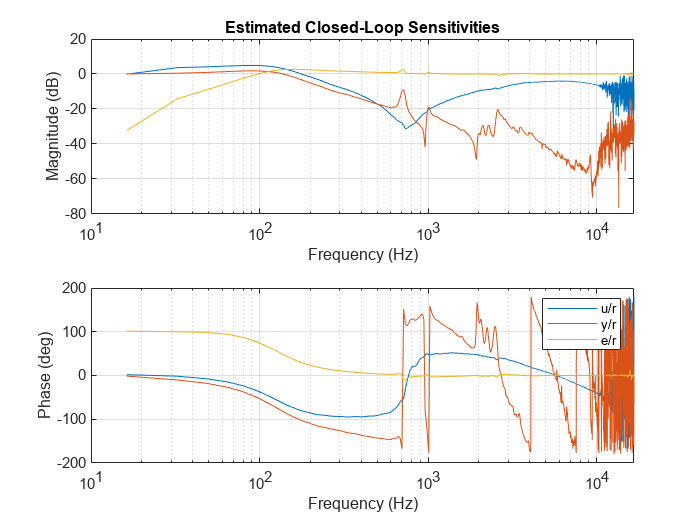


ft10 = (0:N-1) * Fs / N; % Frequency vector (up to Fs)

% Get input-output signal pairs
inpt = r;
outpt = u; %u/r

inpt2 = r;
outpt2 = y; %y/r

inpt3 = r;
outpt3= e; %e/r

% Use tfestimate() function 

N_w = 2048;               % Window length (e.g., 2048 samples)
O = round(0.5 * N_w);     % 50% overlap
wind = hann(N_w);         % Hann window

% Similarly, for overlap, if necessary
% Evaluate coherence!

[T,f] = tfestimate(inpt,outpt,wind,O,N_w,Fs); %u/r
[C,f] = mscohere(inpt,outpt,wind,O,N_w,Fs);

[T2,f2] = tfestimate(inpt2,outpt2,wind,O,N_w,Fs); %y/r
[C2,f2] = mscohere(inpt2,outpt2,wind,O,N_w,Fs);

[T3,f3] = tfestimate(inpt3,outpt3,wind,O,N_w,Fs); %e/r
[C3,f3] = mscohere(inpt3,outpt3,wind,O,N_w,Fs);


% Plot Closed-Loop Identified Sensitivities
figure(1);clf(1); 
subplot(2,1,1);
semilogx(f,mag2db(abs(T))); hold on;
semilogx(f,mag2db(abs(T2))); hold on;
semilogx(f,mag2db(abs(T3))); hold on;
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid on
title('Estimated Closed-Loop Sensitivities')
subplot(2,1,2);
semilogx(f,rad2deg(angle(T))); hold on;
semilogx(f,rad2deg(angle(T2))); hold on;
semilogx(f,rad2deg(angle(T3))); hold on;
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
legend('u/r','y/r','e/r')
grid on

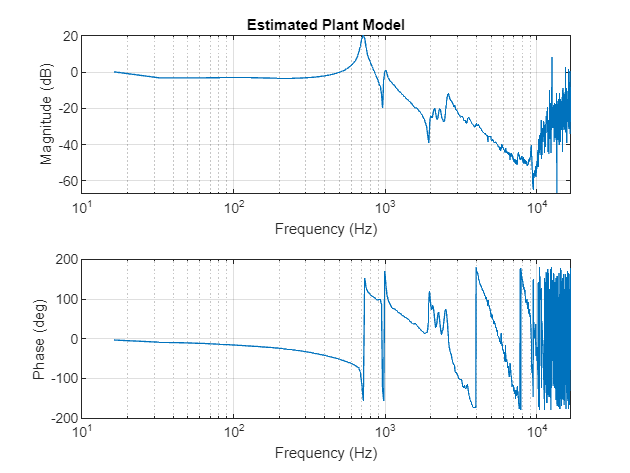


%Derivation of plant from estimated transfer functions

Pestimate = T2./T; % -(e/f)/(u/f)

% Plot Plant
figure(1);clf(1);
subplot(2,1,1);semilogx(f,mag2db(abs(Pestimate)));
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid on
title('Estimated Plant Model')
subplot(2,1,2);semilogx(f,rad2deg(angle(Pestimate)));
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
grid on

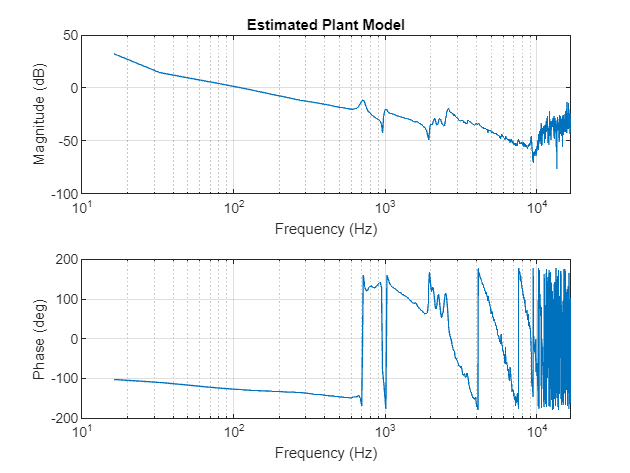


%Derivation of plant from estimated transfer functions

Cestimate = T2./T3; % -(e/f)/(u/f)

% Plot Plant
figure(2);clf(2);
subplot(2,1,1);semilogx(f,mag2db(abs(Cestimate)));
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid on
title('Estimated Plant Model')
subplot(2,1,2);semilogx(f,rad2deg(angle(Cestimate)));
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
grid on


%%Assignment 3 - Part B: Dynamic Error Budgeting

signals = load("MSD2024_P3_Signals.mat")

signals = struct with fields:
    d: [0.1111 0.1280 0.0752 0.3456 0.3512 0.4129 0.3293 0.4960 0.3825 0.2846 0.2753 0.2691 0.2238 0.1622 0.2969 0.4776 0.4916 0.6654 0.8661 0.5871 0.8467 1.1441 0.9625 0.9685 0.8569 0.9311 0.8853 0.7758 1.0920 0.8866 1.0022 1.2366 1.2498 1.1722 … ]
    n: [0.1554 0.2295 0.2396 0.2931 0.4492 0.4554 0.4298 0.4457 0.3611 0.1855 0.0961 0.1328 0.0995 0.0030 -0.0243 -0.1980 -0.0559 0.2052 0.1036 0.0469 0.3695 0.3158 0.4863 0.5628 0.5485 0.5734 0.6548 0.4337 0.6353 0.4821 0.8086 0.6854 0.5660 0.6563 … ]


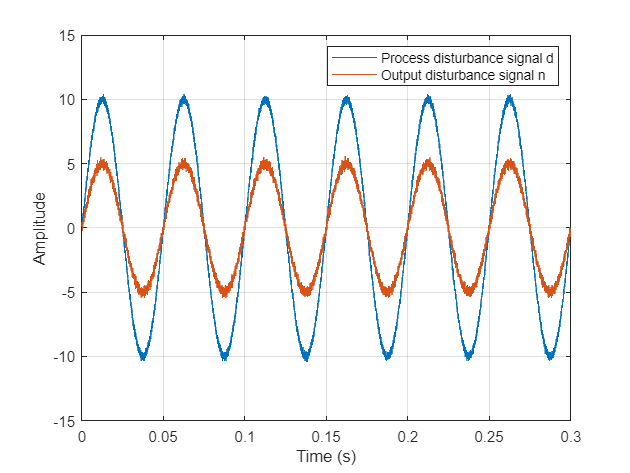


Ts = 30e-6; % [s] sample time
Fs = 1/Ts; % [Hz] Sample Frequency

d = signals.d;
n = signals.n;

N = length(d);    % Number of samples
t = (0:N-1) * Ts; % Time vector [s] 

% (B.1) Plot Signals in time domain
figure(1); clf(1);
plot(t, d, 'DisplayName', 'Process disturbance signal d'); % Input signal
hold on;
plot(t, n, 'DisplayName', 'Output disturbance signal n'); % Measured output
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('show');


%%Convert the time signals into frequency responses using Fourier
%%transforms: fft function will give the fourier transform of the time
%%signals

D = fft(d); %Fourier-tranformed signal d
Nfft = fft(n); %Fourier-transformed signal n
f_vector = (0:N-1) * Fs / N;  

% Plot Fourier-transformed signals spectra
figure(1); clf(1);
plot(f_vector, D, 'DisplayName', '|D(f)|');

hold on;
plot(f_vector, Nfft, 'DisplayName', '|N(f)|');

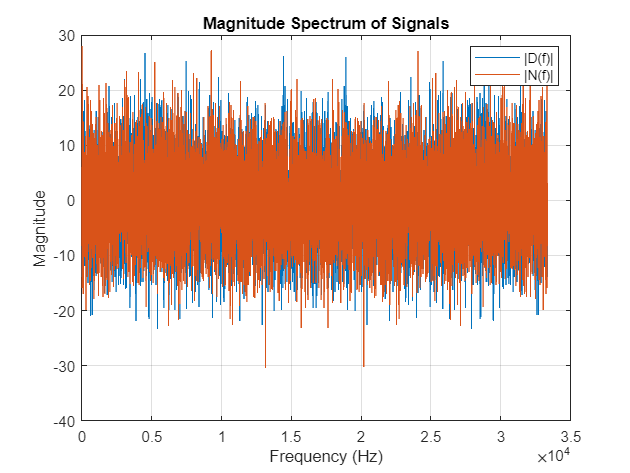

grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('show');
title('Magnitude Spectrum of Signals');

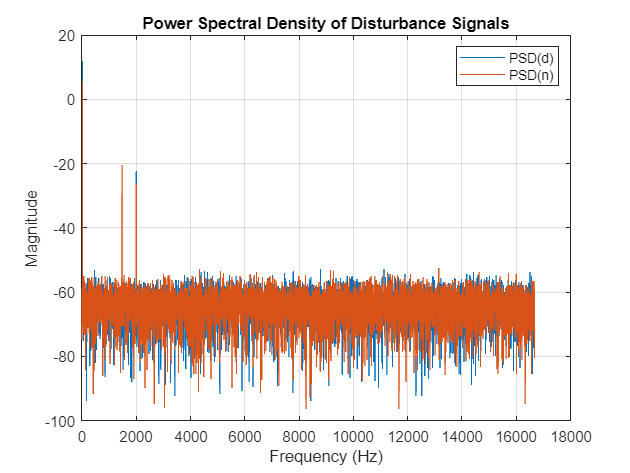


%(B.2) Computation of PSD for each disturbance signal
%Computation of the closed-loop transfer functions for d and n
%From the scheme of the system, it is clear that the transfer function of
%the disturbance signals are:

H_d = P / (1 + L2); %Closed-loop Transfer function of d of the system without feedforward

H_n = 1 / (1 + L2); %Closed-loop Transfer function of n of the system without feedforward

freq = 0:Fs/length(d):Fs/2; %Go until Nyquist frequency

% Frequency response of H_d and H_n - Evaluate the responses in rad/s 
[H_d_f, ~] = freqresp(H_d, 2 * pi * freq);
[H_n_f, ~] = freqresp(H_n, 2 * pi * freq);

% Compute PSDs
%Computation of PSD of D
D_real = D(1:N/2 + 1); %Get the real values and work with them
psd_d = (1/(Fs*N)) * abs(D_real).^2; %Computation of PSD
psd_d(2:end-1) = 2*psd_d(2:end-1); %Double PSD values except for the first (DC) and the last (Fs/2)

%Computation of PSD of Nfft
Nfft_real = Nfft(1:N/2 + 1); %Get the real values and work with them
psd_n = (1/(Fs*N)) * abs(Nfft_real).^2; %Computaton of PSD
psd_n(2:end-1) = 2*psd_n(2:end-1); %Double PSD values except for the first (DC) and the last (Fs/2)

%Plot of PSD signals
figure(1); clf(1);
plot(freq, pow2db(psd_d) , 'DisplayName', 'PSD(d)');
hold on;
plot(freq, pow2db(psd_n), 'DisplayName', 'PSD(n)');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('show');
title('Power Spectral Density of Disturbance Signals');

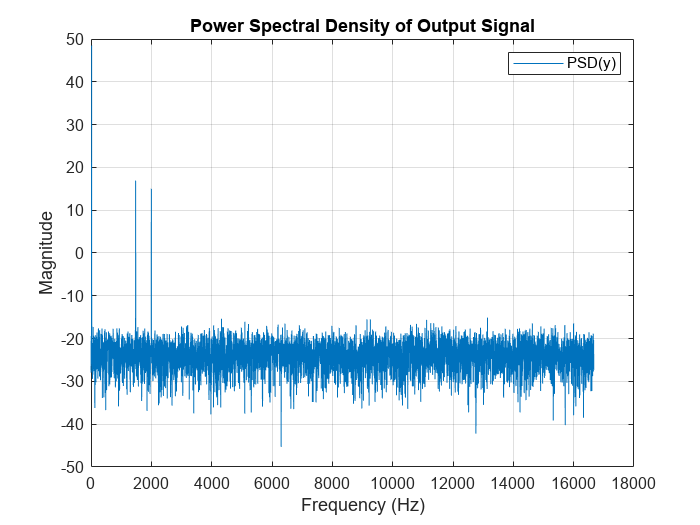


%(B.3) Computation of the combined PSD output signal using PSD(d) and
%PSD(n)

% Initialize psd_y: it should have same length as psd_d and psd_n
psd_y = zeros(size(psd_d));  

% Sum the contributions of each output
for i = 1:size(H_d_f, 3)
    % Computation of the magnitude of current output
    H_d_f_magnitude = abs(H_d_f(:,:,i));  
    H_n_f_magnitude = abs(H_n_f(:,:,i));  
    
    % Computation of PSD contributions for the current output
    S_y_d = (H_d_f_magnitude.^2) .* psd_d;  % Contribution of PSD(d)
    S_y_n = (H_n_f_magnitude.^2) .* psd_n;  % Contribution of PSD(n)
    
    psd_y = psd_y + S_y_d + S_y_n;  
end

%Plot of PSD(y)
figure;
plot(freq, pow2db(psd_y), 'DisplayName', 'PSD(y)');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('show');
title('Power Spectral Density of Output Signal')

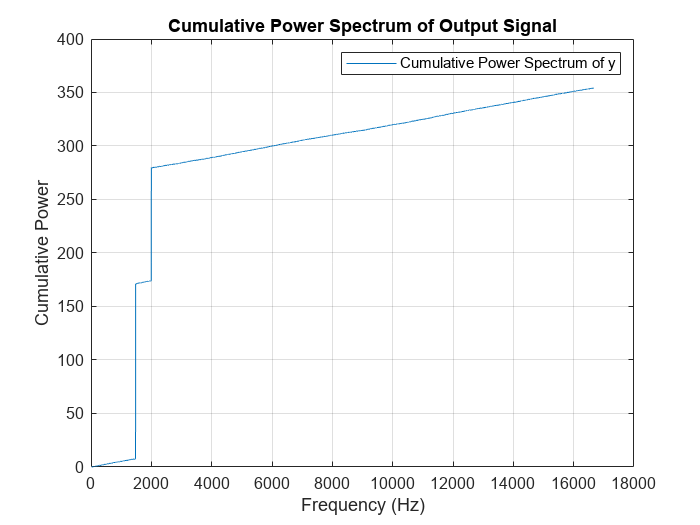


%(B.4) Computation of Cumulative Power Spectrum of the output signal y

% Calculate the Cumulative Power Spectrum (CPS) by summing the PSD values
%Starting from the eight point because 7th value of psd_y is weird, leading
%to complete different results

cps_y = cumsum(psd_y(8:end) * (freq(2) - freq(1))); % Cumulative sum of PSD (multiplying by the frequency step)

% Plot the Cumulative Power Spectrum
figure;
plot(freq(8:end), (cps_y), 'DisplayName', 'Cumulative Power Spectrum of y');
grid on;
xlabel('Frequency (Hz)');
ylabel('Cumulative Power');
legend('show');
title('Cumulative Power Spectrum of Output Signal');

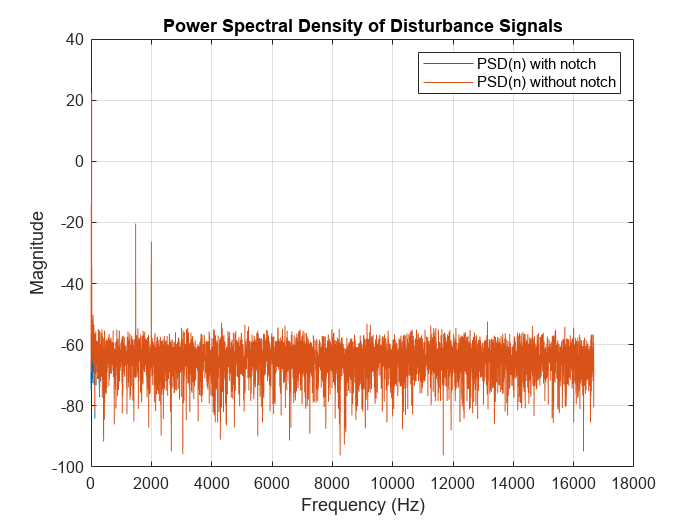


%(B.5) Re-computation of CPS and PSD with notch filter N2 applied

%Fourier transform of Notch trasnfer function ---> Frequency response of
%transfer function
omega = 2 * pi * f_vector;

[N2_fft, ~] = freqresp(N2, omega); % Frequency response of N2

N2_fft = squeeze(N2_fft)';

Nfft_new = Nfft .* N2_fft;

%Fourier transform of filtered disturbance signal
Nfft_new_real = Nfft_new(1:N/2 + 1);
psd_n_new = (1/(Fs*N)) * abs(Nfft_new_real).^2;
psd_n_new(2:end-1) = 2*psd_n_new(2:end-1);

%Plot of PSD signals
figure(1); clf(1);
plot(freq, pow2db(psd_n) , 'DisplayName', 'PSD(n) with notch');
hold on;
plot(freq, pow2db(psd_n_new), 'DisplayName', 'PSD(n) without notch');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('show');
title('Power Spectral Density of Disturbance Signals');

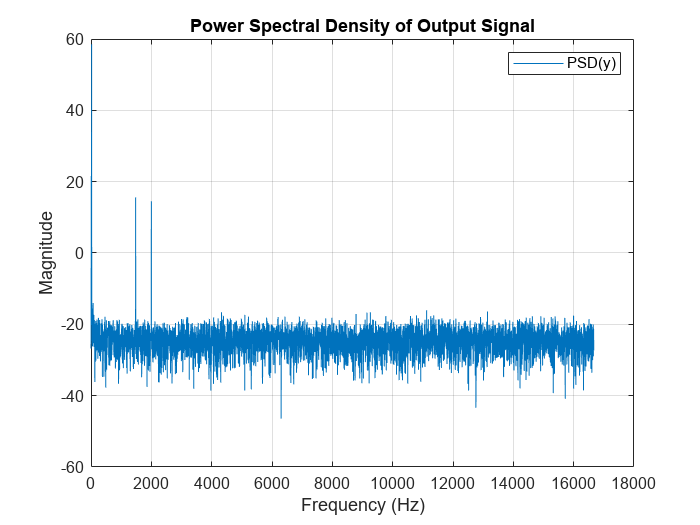


H_n_new = H_n * N2;

[H_n_new_f, ~] = freqresp(H_n_new, freq);
% Initialize variables
psd_y_new = zeros(size(psd_d));  % Initialize the PSD of the output signal (same size as psd_d)

% Sum the contributions of each output
for i = 1:size(H_d_f, 3)
    % Computation of the magnitude of the current output
    H_d_f_magnitude = abs(H_d_f(:,:,i));  % Select magnitude for output i
    H_n_new_f_magnitude = abs(H_n_new_f(:,:,i));  % Select magnitude for output i
    
    % Computation of PSD contributions for the current output
    S_y_d = (H_d_f_magnitude.^2) .* psd_d;  % Contribution of PSD(d)
    S_y_n_new = (H_n_new_f_magnitude.^2) .* psd_n_new;  % Contribution of PSD(n)
    
    % Add the contributions to the total PSD (this accumulates the result)
    psd_y_new = psd_y_new + S_y_d + S_y_n_new;  % Sum the contributions
end

%Plot of PSD(y)
figure;
plot(freq, pow2db(psd_y_new), 'DisplayName', 'PSD(y)');
hold on;
plot(freq, pow2db(psd_y), 'DisplayName', 'PSD(y)');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('show');
title('Power Spectral Density of Output Signal')

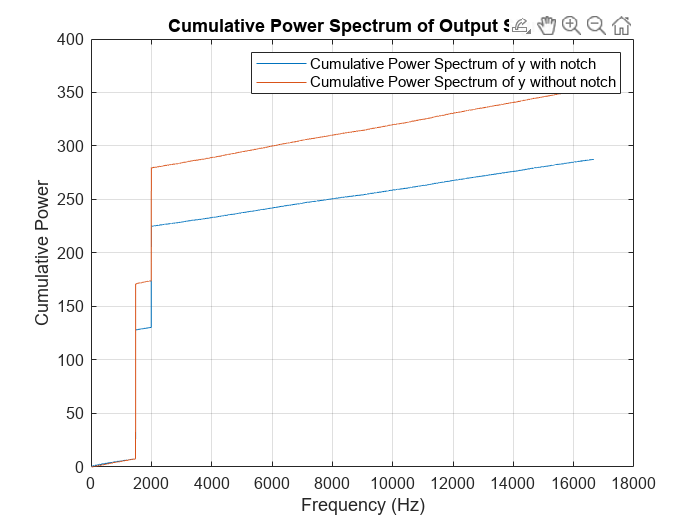


cps_y_new = cumsum(psd_y_new(8:end) * (freq(2) - freq(1))); % Cumulative sum of PSD (multiplying by the frequency step)

% Plot Cumulative Power Spectrums and compare
figure;
plot(freq(8:end), (cps_y_new), 'DisplayName', 'Cumulative Power Spectrum of y with notch');
hold on;
plot(freq(8:end), (cps_y), 'DisplayName', 'Cumulative Power Spectrum of y without notch');
grid on;
xlabel('Frequency (Hz)');
ylabel('Cumulative Power');
legend('show');
title('Cumulative Power Spectrum of Output Signal');